% adding cross section to 3D scatter
global plot_range thickness i_cells;
plot_range = [-100 100 -100 100 0 35];
i_cells =118;
for n = 1:4
    file_path = sprintf('data/Cells%d/%d.txt',n,i_cells);
    if n == 1
        cells = importdata(file_path);
    else
        cells = cat(1,cells,importdata(file_path));
    end
end
x1 = cells(:,4);
x2 = cells(:,7);
y1 = cells(:,5);
y2 = cells(:,8);
z1 = cells(:,6);
z2 = cells(:,9);
lengths = cells(:,10);
c1 = cells(:,27); % p age
c2 = cells(:,28); % q age

c = (c1 + c2)/2; % average pole age for cells
% average co-ordinates
x = (x1 + x2)/2;
y = (y1 + y2)/2;
z = (z1 + z2)/2;

%radial distance of cell
%Using the "." will effectively perform element-by-element mathematical operations
r = sqrt(x.^2 + y.^2);
clear x1 x2 y1 y2 z1 z2 c1 c2;

Determines the size of the dots used in scatter plots, and the thickness of all planar cross sections

global thickness dot_size;
dot_size =2;
thickness =1;

cells possition plotted as points with color representing the cell's average pole age

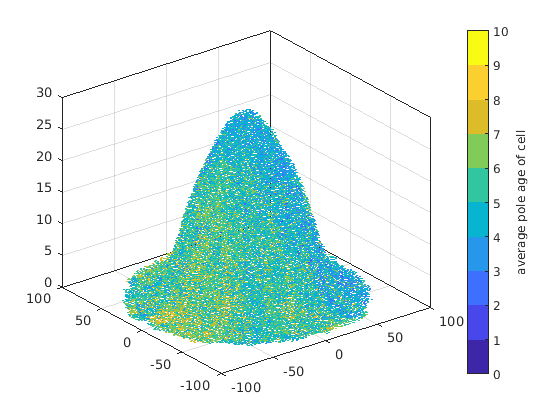

plt.plot(x,y,z,dot_size,c, "average pole age of cell")

cross sections of the above plot in all 3 principle directions

z_cut =2;
plt.plot(x,y,z,dot_size,c, "average pole age of cell", 'Z',z_cut)

x_cut =38;
plt.plot(x,y,z,dot_size,c, "average pole age of cell", 'X',x_cut)

y_cut =22;
plt.plot(x,y,z,dot_size,c, "average pole age of cell", 'Y',y_cut)

cells are drawn as line segments, with color representing the cell length

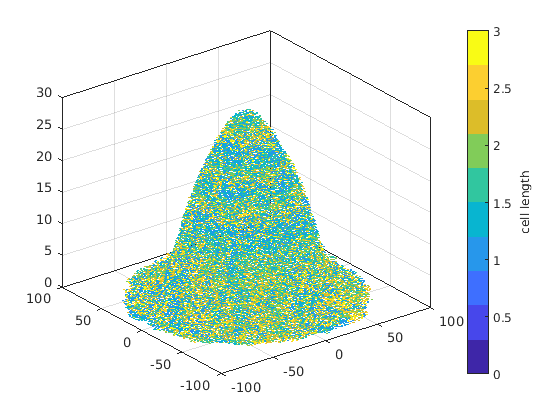

plt.plot(x,y,z,dot_size,lengths, "cell length")

cross sections of the above plot in all 3 principle directions

z_cut =8;
plt.plot(x,y,z,dot_size,lengths, "cell length",'Z',z_cut)

x_cut =8;
plt.plot(x,y,z,dot_size,lengths, "cell length",'X',x_cut)

y_cut =15;
plt.plot(x,y,z,dot_size,lengths, "cell length",'Y',y_cut)

age plot trimmed to a radius

r_cut =28;
tube_thickness = 1;
i = find(r>r_cut & r<(r_cut+tube_thickness));

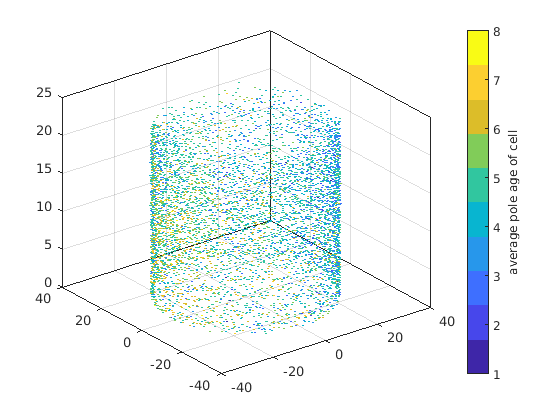

plt.plot(x(i),y(i),z(i),dot_size,c(i), "average pole age of cell")

length plot trimmed to a radius

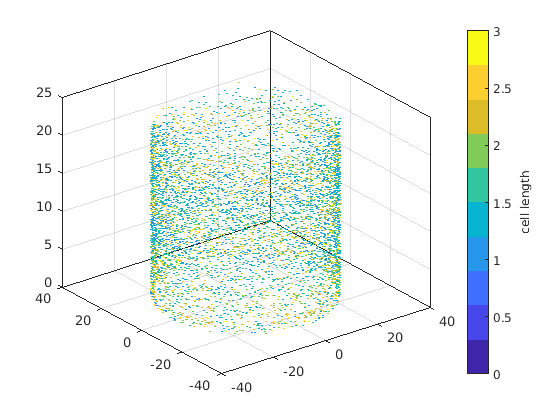

plt.plot(x(i),y(i),z(i),dot_size,lengths(i), "cell length")

graphing average cell age for a certain radius as a 2d plot

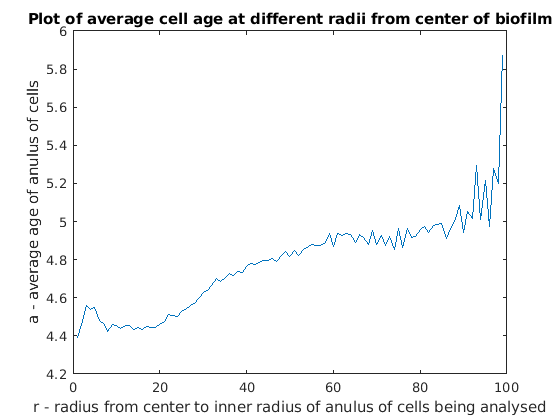

res = 1; %thickness of tubes being analysed
max_r = 100;
r_range = 1:res:(max_r-res); %https://uk.mathworks.com/help/matlab/ref/colon.html
avg_age = r_range;
for i = 1:length(r_range)
    ring_indeces = find(r>r_range(i) & r<(r_range(i)+res));
    avg_age(i) = mean(c(ring_indeces), 'all');
end
plot(r_range,avg_age)

title('Plot of average cell age at different radii from center of biofilm')
xlabel('r - radius from center to inner radius of anulus of cells being analysed')
ylabel('a - average age of anulus of cells')